# Design of Experiments for Polymer Pellet Development

Explore how selected process factors may relate to a synthetic pellet-quality response.

All factor ranges and response values are illustrative. Replace them only after PTTGC defines safe, approved experimental ranges.

## Engineering question

Product development and process engineering teams often need to learn which controllable factors influence a response such as melt-flow index or pellet strength. Designed experiments help separate factor effects and interactions more efficiently than changing several settings without a plan.

**Agent prompt:** Explain main effects and interactions for a two-factor experiment. Identify why observational production data alone may not establish causation.

## Review the synthetic experiment

dataFolder = fullfile(pwd,"data");
doeData = readtable(fullfile(dataFolder,"polymer_pellet_doe.csv"));
doeData

doeData = 16×6 table
    run    MeltTemp_C    ScrewSpeed_rpm    Additive_wtPct    MeltFlowIndex_g10min    PelletStrength_MPa
    ___    __________    ______________    ______________    ____________________    __________________

     1        205             300               0.2                 4.4708                  30.01      
     2        205             300               0.2                 4.6755                 29.721      
     3        205             300               0.6                  5.105                 32.338      
     4        205             300               0.6                 5.0966                 32.132      
     5        205             500               0.2                 4.6307                 29.982      
     6        205             500             

factorNames = ["MeltTemp_C","ScrewSpeed_rpm","Additive_wtPct"];
responseName = "MeltFlowIndex_g10min";

## Visualize the response

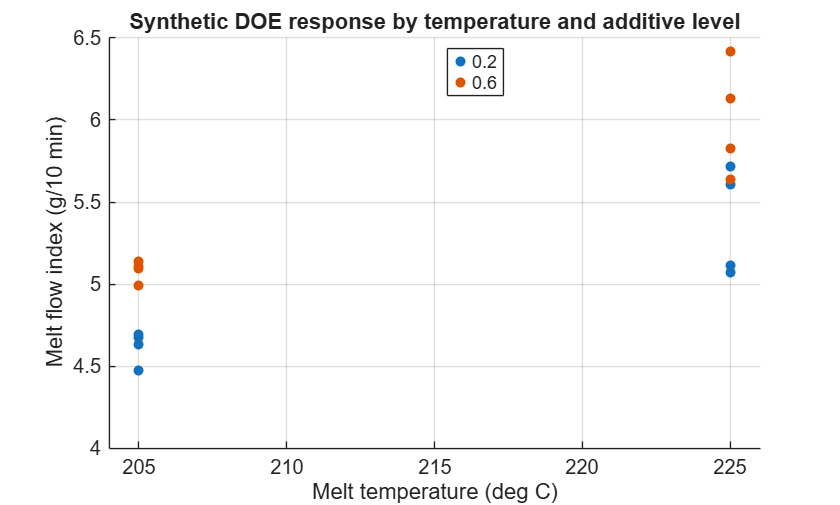

gscatter(doeData.MeltTemp_C,doeData.MeltFlowIndex_g10min,doeData.Additive_wtPct)
xlabel("Melt temperature (deg C)")
ylabel("Melt flow index (g/10 min)")
title("Synthetic DOE response by temperature and additive level")
grid on

**Agent prompt:** Describe the pattern in the plot and list plausible confounding factors that should be controlled or recorded during a real experiment.

## Fit a simple interaction model

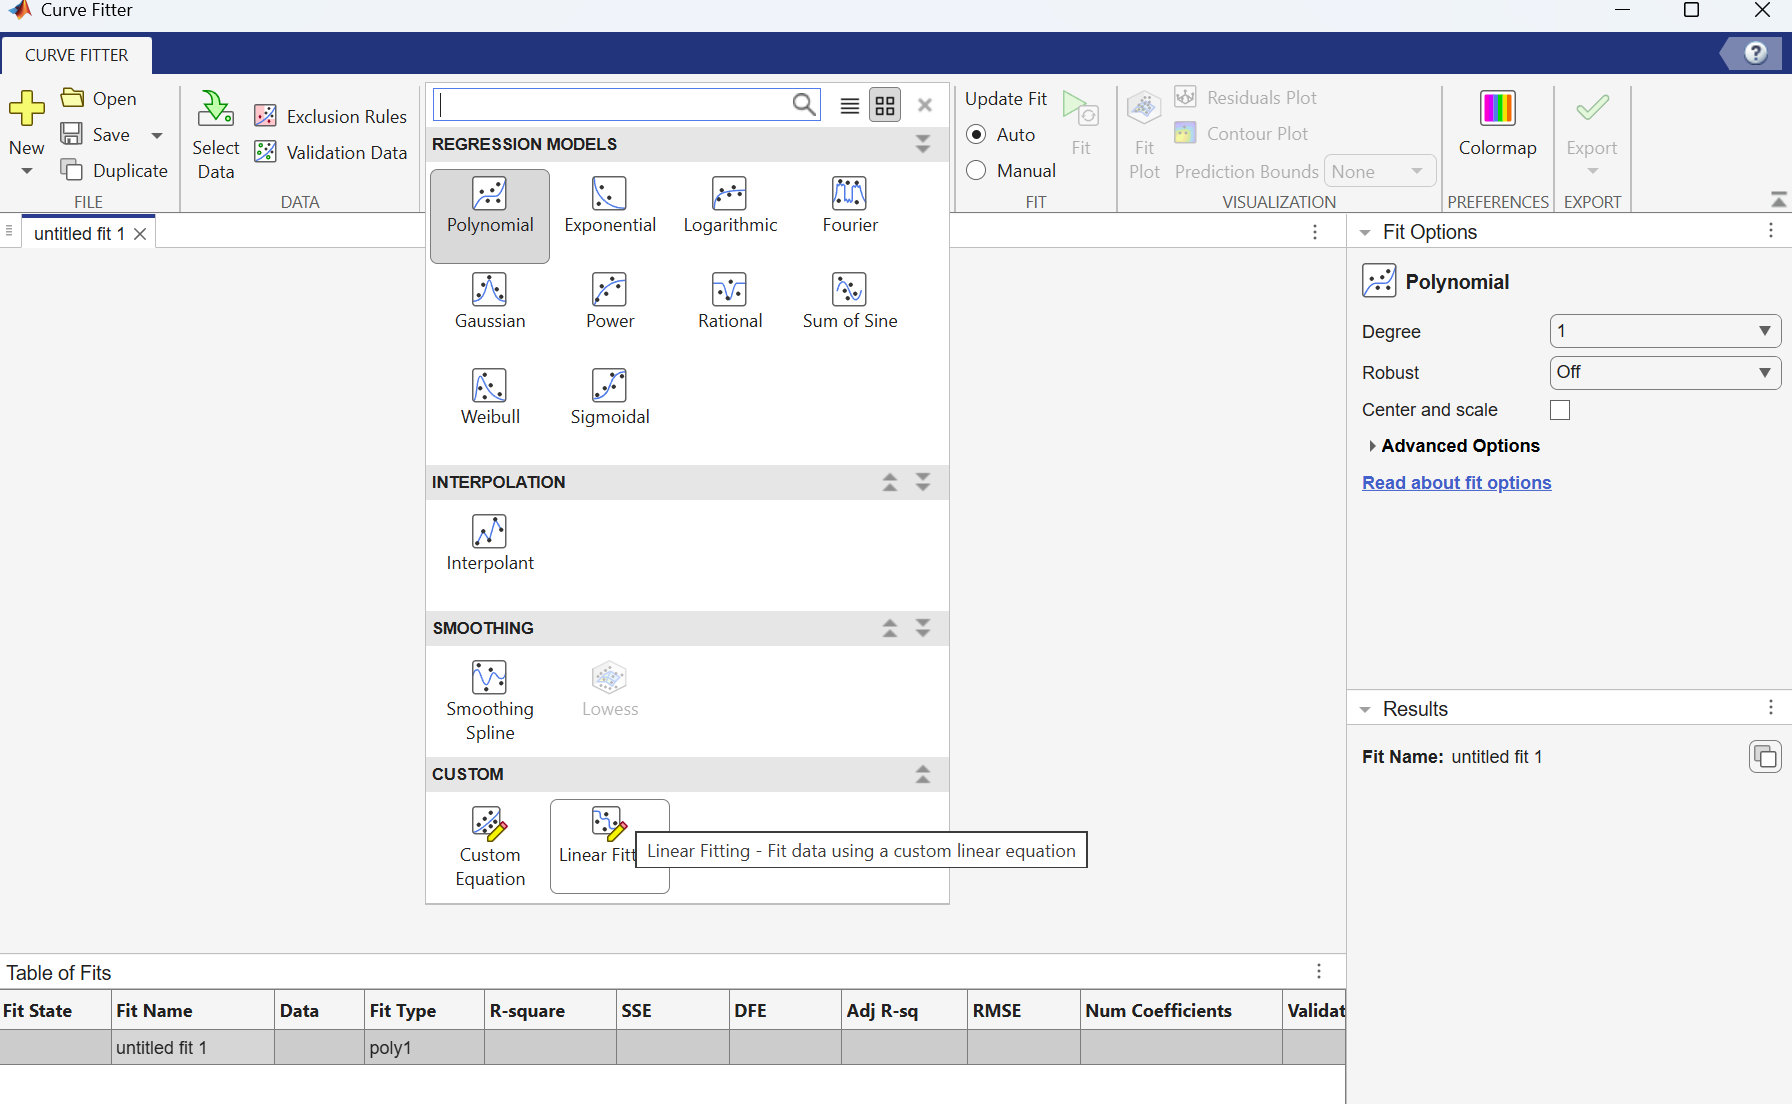

doeModel = fitlm(doeData,"MeltFlowIndex_g10min ~ MeltTemp_C*ScrewSpeed_rpm + Additive_wtPct");
doeModel

doeModel = Linear regression model:
    MeltFlowIndex_g10min ~ 1 + Additive_wtPct + MeltTemp_C*ScrewSpeed_rpm

Estimated Coefficients:
                                  Estimate         SE         tStat        pValue  
                                 __________    __________    ________    __________

    (Intercept)                      6.5191        2.4323      2.6802        0.0214
    MeltTemp_C                     -0.01106      0.011298    -0.97896       0.34864
    ScrewSpeed_rpm                -0.027036     0.0058978     -4.5841    0.00078506
    Additive_wtPct                    1.364       0.13701      9.9554    7.7304e-07
    MeltTemp_C:ScrewSpeed_rpm    0.00013253    2.7402e-05      4.8364    0.00052195


Number of observations: 16, Error degrees of freedom:

anova(doeModel,"summary")

ans = 7×5 table
                      SumSq      DF     MeanSq        F         pValue  
                     ________    __    ________    _______    __________

    Total              4.7595    15      0.3173                         
    Model              4.6273     4      1.1568     96.292    1.7454e-08
    . Linear           4.3463     3      1.4488     120.59    1.0709e-08
    . Nonlinear       0.28102     1     0.28102     23.391    0.00052195
    Residual          0.13215    11    0.012014                         
    . Lack of fit    0.034719     3    0.011573    0.95025       0.46111
    . Pure error     0.097432     8    0.012179                         


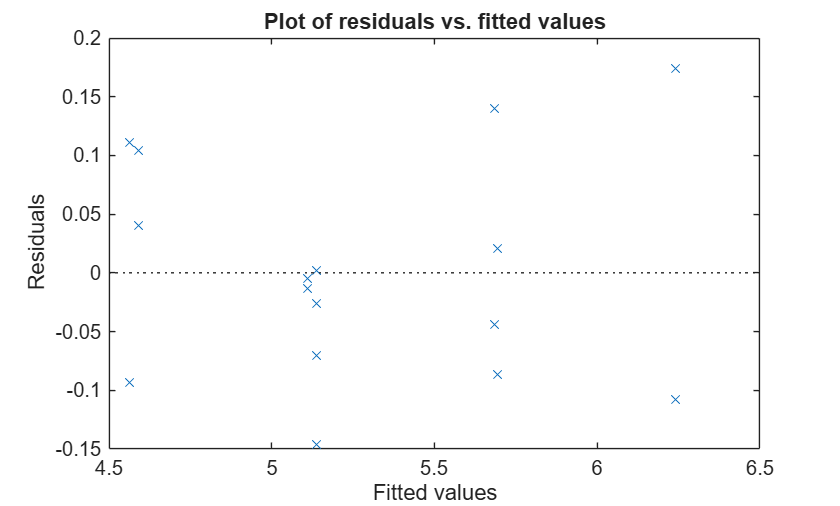

plotResiduals(doeModel,"fitted")

Interpret coefficient units and residual diagnostics before considering a process recommendation. A statistically detectable effect does not automatically imply a practically important or safe change.

**Agent prompt:** Summarize this model for a process engineer. Separate evidence from hypotheses, explain the interaction term, and state what additional confirmation runs are needed before changing a production recipe.

## Explore DOE Explorer in R2026b

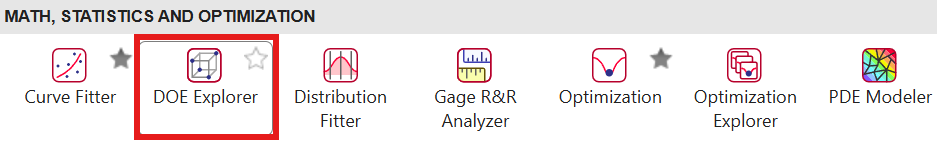

Open Apps and select DOE Explorer. Create a small factorial design with approved factors and levels, randomize run order when appropriate, and review the generated run plan. The app can help explore a design; process safety and experiment authorization remain with PTTGC.

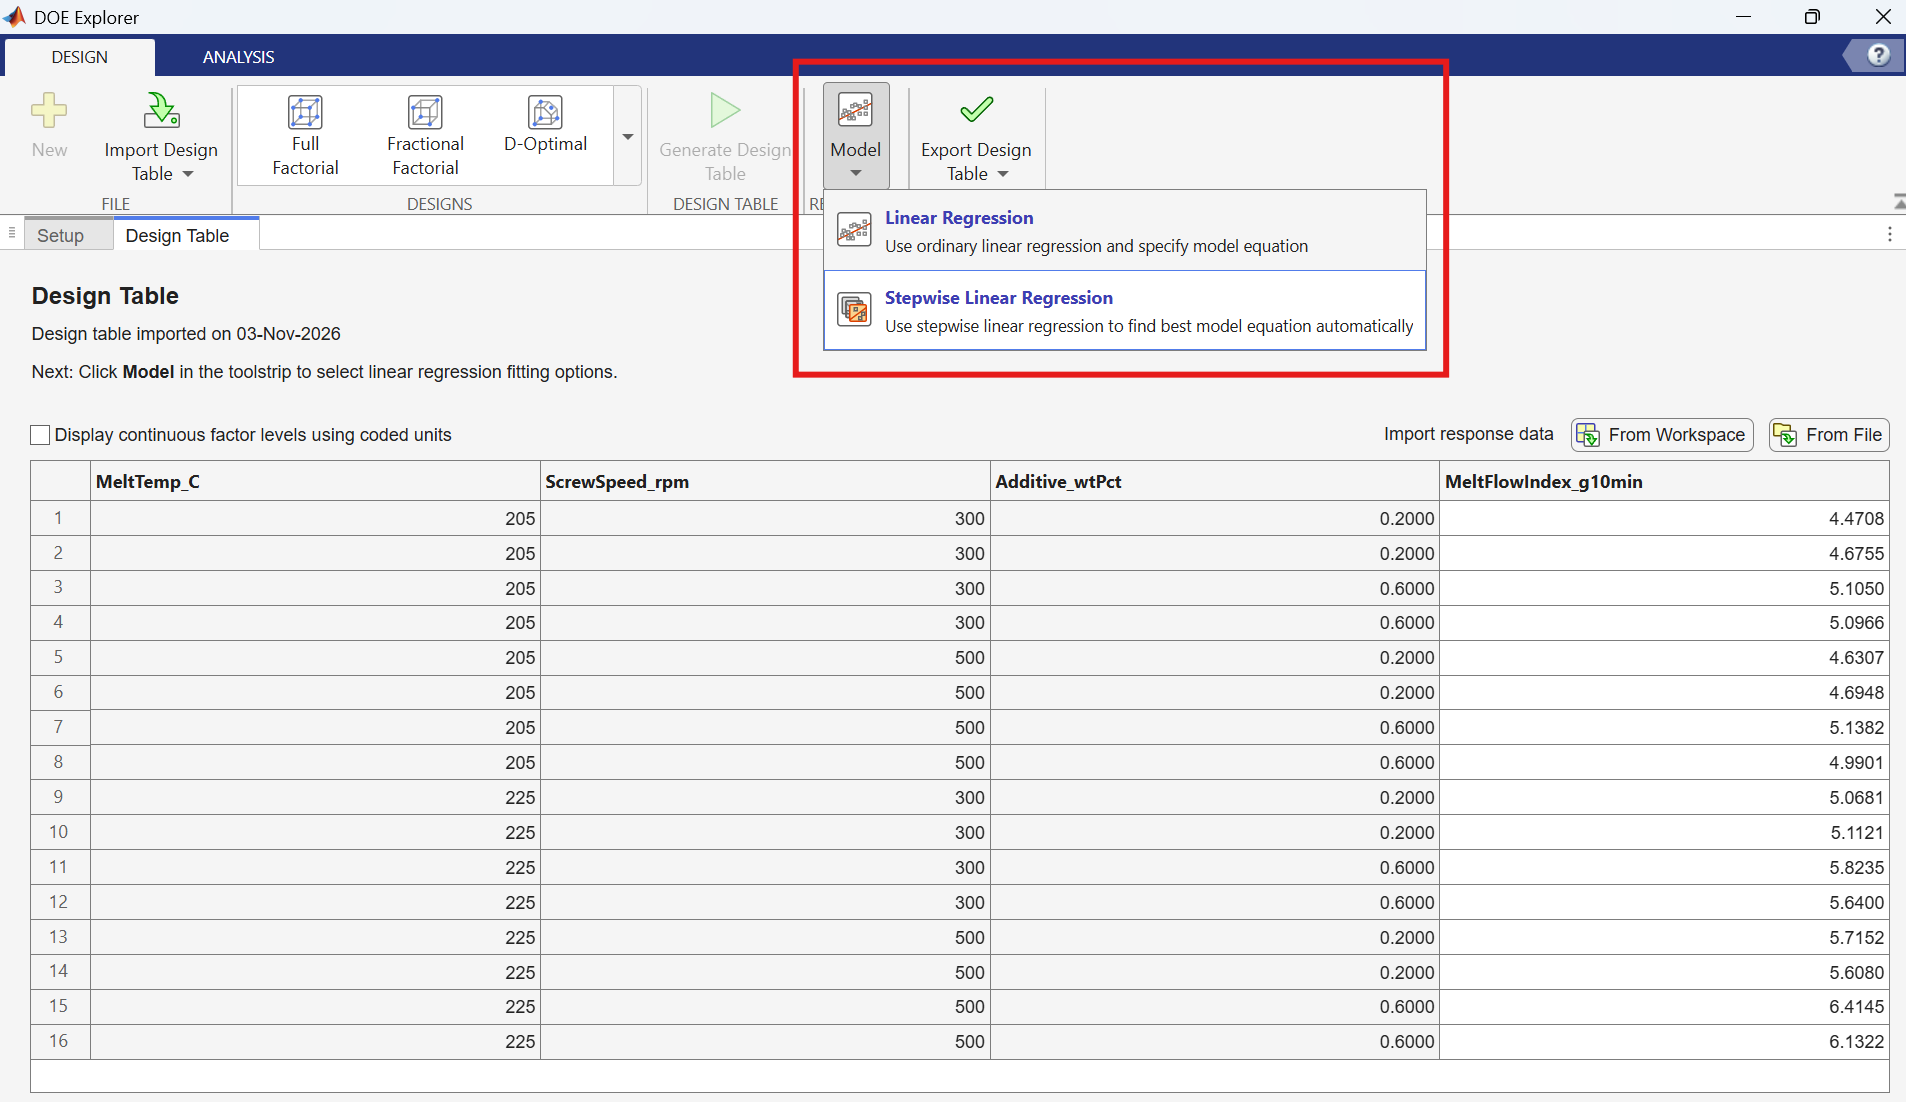

**Agent prompt:** Propose a DOE planning checklist for polymer pellet development. Ask for response definition, factor ranges, blocking variables, replicate plan, randomization constraints and safety approvals before creating a design.

## Discussion

Which product response matters most to PTTGC: melt-flow behavior, pellet dimensions, mechanical performance, or another laboratory result? Which factors can the team vary safely and repeatably? \